# **Final Project**

### **DATA604**

## **USPS Handwritten Digits Dataset Analysis**

**Name: Shrey Patel**

**A comparative analysis of the usefulness of using representation methods for classification, based on the USPS handwritten digits dataset. Idea is to represent the data in the best way possible such that it easier for our algorithms to classify or cluster.**

tic
% Loading the dataset
% Dimension = 256x1100x10
% 256 pixels, 1100 instances of 10 digits(1,2,...9,0)
load usps_all.mat

% Train/test split - 1050/50 (optimal) {Project 1}
% First 1050 examples/instances of each digit in training set 
% and the rest 50 in the test set.
train = data(:,1:1050,:);
test = data(:,1051:end,:);

% Stretching the train and test datasets, such that each set of 
% 1100 rows belong to a digit, and each row is an instance of a digit,
% while the columns are the dimensions.
train = train(:,:)';
test = test(:,:)';

% creating training and testing set labels
for i = 1:1050:10500
    train_label(i:i+1049,:) = ceil(i/1050);
end
for i = 1:50:500
    test_label(i:i+49,:) = ceil(i/50);
end

#### -------------------------------------------------

#### Method 1. Raw Data

***I. Performing Validation - to find an optimal k for kNN***

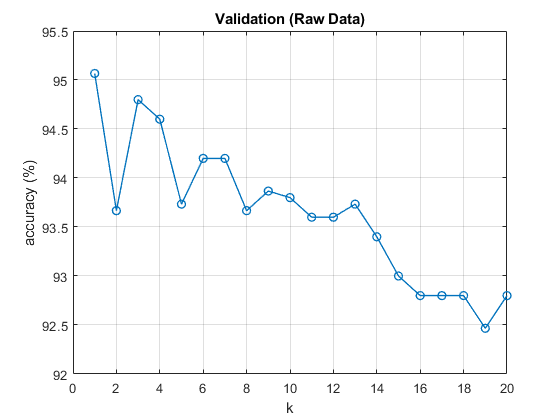

% splitting data into a subset of training-set(x_sub_train) {first 900 examples} 
% and validation-set(x_valid) {next 150 examples} . Last 50 examples are
% left untouched solely for testing.
x_sub_train = zeros(256,900,10); % [256x900x10]
x_valid = zeros(256,150,10); % [256x150x10]
for i = 1:10
    x_sub_train(:,:,i) = data(:,1:900,i);
    x_valid(:,:,i) = data(:,901:1050,i);
end

% reshaping
x_sub_train = x_sub_train(:,:)';
x_valid = x_valid(:,:)';

% creating training and validation labels
for i = 1:900:9000
    subtr_label(i:i+899,:) = ceil(i/900);
end
for i = 1:150:1500
    val_label(i:i+149,:) = ceil(i/150);
end
accuracy = zeros(20,1);
for k = 1:20
    idx = knnsearch(double(x_sub_train),double(x_valid),'K',k,...
        'Distance',"euclidean");
    idc = ceil(idx/900);
    pred_labels = mode(idc,2);
    accuracy(k,:) = (1-(length(find(pred_labels~=val_label))/1500))*100;
end
[val,pos(1)] = min(abs(accuracy-mean(accuracy)));
figure;
plot(accuracy,'-o','MarkerIndices',1:1:20,'DisplayName','Accuracy','LineWidth',1);
title('Validation (Raw Data)')
xlabel('k')
ylabel('accuracy (%)')
grid on;

***II. kNN***

% Each test row is a query point that needs to be classified and 
% each train row is an observation.
% cross-validation
k = pos(1); %optimal k
idx = knnsearch(double(train),double(test),'K',k,'Distance',"euclidean");
idc = ceil(idx/1050);
pred_labels = mode(idc,2);
acc = zeros(4,1);
acc(1,:) = (1-(length(find(pred_labels~=test_label))/500))*100;
fprintf("Global accuracy score with raw data for k = %d is %f percent\n",k,acc(1,:));

Global accuracy score with raw data for k = 11 is 93.200000 percent


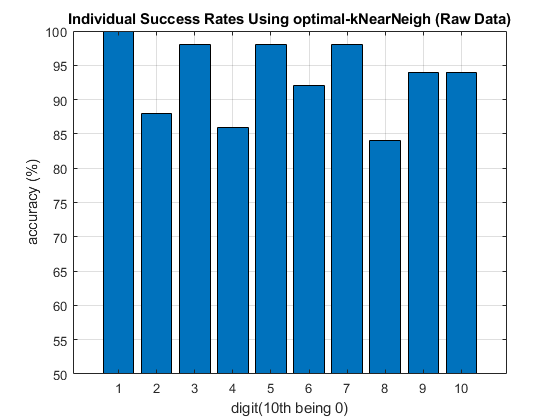


success_rate = zeros(10,4);
for i = 1:50:500
    success_rate(ceil(i/50),1)=(1-(length(find(pred_labels(i:i+49)~=test_label(i:i+49)))/50))...
                                *100;
end

bar(success_rate(:,1))
title('Individual Success Rates Using optimal-kNearNeigh (Raw Data)')
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')
ylim([50,100])

***III. kSVM***

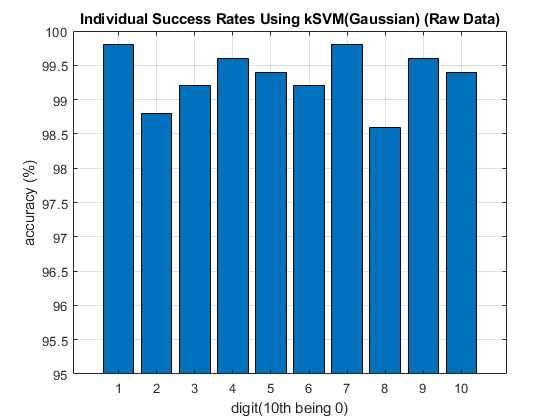

% Performing two-class classification for each digit
accuracy_score = zeros(10,4);
for i = 1:10
    k_train_label = zeros(10500,1)-1;
    k_test_label = zeros(500,1)-1;
    k_train_label(find(train_label==i)) = i;
    k_test_label(find(test_label==i)) = i;
    SVMmodel = fitcsvm(double(train),k_train_label,'KernelFunction','rbf'...
                    ,'KernelScale','auto','Standardize',true);
    classes = SVMmodel.ClassNames;
    [label, score] = predict(SVMmodel,double(test));
    correct_label = length(find(label==k_test_label));
    accuracy_score(i,1) = (correct_label/500)*100;
    %fprintf('Global Accuracy Score for digit %d using fitcsvm(rbf) is %f percent\n'...
    %       ,i,accuracy_score(i,:));
end

bar(accuracy_score(:,1))
title('Individual Success Rates Using kSVM(Gaussian) (Raw Data)')
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')
ylim([95,100])

#### -------------------------------------------------

#### Method 2. Principal Component Analysis

***I. Performing PCA on the whole dataset using DR-Toolbox for MATLAB***

digits = data(:,:)';
dim = 225;
[mapped_data, mapping] = compute_mapping(digits, 'PCA', dim);
%P = double(digits)*(mapping.M);
%imshow(reshape(P(33,:),[15 15]),[])
train = zeros(dim,1050,10);
test = zeros(dim,50,10);
t = 1;
for i = 1:1100:11000
    train(:,:,t) = mapped_data(i:i+1049,:)';
    test(:,:,t) = mapped_data(i+1050:i+1099,:)';
    t = t+1;
end

***II. Performing Validation for kNN***

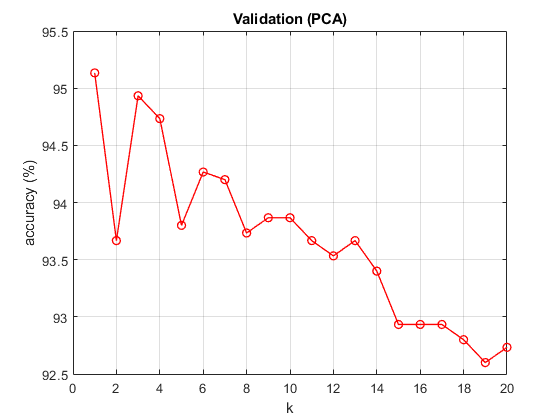

% splitting data into a subset of training-set(x_sub_train) {first 900 examples} 
% and validation-set(x_valid) {next 150 examples} . Last 50 examples are
% left untouched solely for testing.
x_sub_train = zeros(dim,900,10); % [dimx900x10]
x_valid = zeros(dim,150,10); % [dimx150x10]
for i = 1:10
    x_sub_train(:,:,i) = train(:,1:900,i);
    x_valid(:,:,i) = train(:,901:1050,i);
end

% reshaping
x_sub_train = x_sub_train(:,:)';
x_valid = x_valid(:,:)';

% training and validation labels stay the same since train-test split is
% unchanged
subtr_label;
val_label;

accuracy = zeros(20,1);
for k = 1:20
    idx = knnsearch(double(x_sub_train),double(x_valid),'K',k,...
        'Distance',"euclidean");
    idc = ceil(idx/900);
    pred_labels = mode(idc,2);
    accuracy(k,:) = (1-(length(find(pred_labels~=val_label))/1500))*100;
end
[val,pos(2)] = min(abs(accuracy-mean(accuracy)));
figure;
plot(accuracy,'-o','MarkerIndices',1:1:20,'DisplayName','Accuracy','LineWidth',1,...
    "Color",'r');
title('Validation (PCA)')
xlabel('k')
ylabel('accuracy (%)')
grid on;

***III. kNN***

train = train(:,:)';
test = test(:,:)';
% train_label and test_label stay the same since our 
% train/split remains unchnaged
train_label;
test_label;

% kNN
% Each test row is a query point that needs to be classified and 
% each train row is an observation.
% cross-validation
k = pos(2); %optimal k
idx = knnsearch(double(train),double(test),'K',k,'Distance',"euclidean");
idc = ceil(idx/1050);
pred_labels = mode(idc,2);
acc(2,:) = (1-(length(find(pred_labels~=test_label))/500))*100;
fprintf("Global accuracy score with PCA data for k = %d is %f percent\n",k,acc(2,:));

Global accuracy score with PCA data for k = 2 is 92.400000 percent


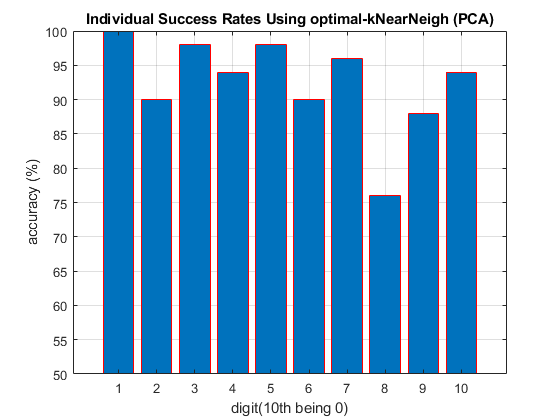


for i = 1:50:500
    success_rate(ceil(i/50),2)=(1-(length(find(pred_labels(i:i+49)~=test_label(i:i+49)))/50))...
                                *100;
end

bar(success_rate(:,2),'EdgeColor','r')
title('Individual Success Rates Using optimal-kNearNeigh (PCA)')
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')
ylim([50,100])

***IV. kSVM***

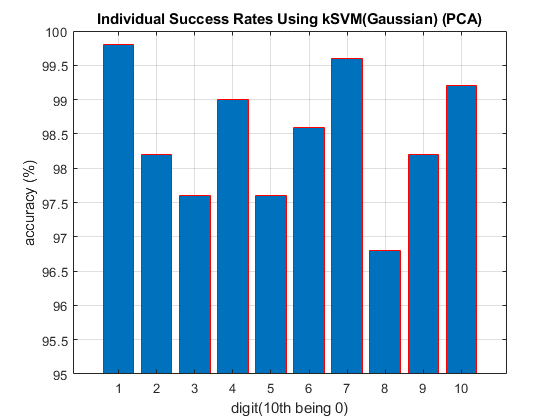

% kSVM
% Performing two-class classification for each digit
for i = 1:10
    k_train_label = zeros(10500,1)-1;
    k_test_label = zeros(500,1)-1;
    k_train_label(find(train_label==i)) = i;
    k_test_label(find(test_label==i)) = i;
    SVMmodel = fitcsvm(double(train),k_train_label,'KernelFunction','rbf'...
                    ,'KernelScale','auto','Standardize',true);
    classes = SVMmodel.ClassNames;
    [label, score] = predict(SVMmodel,double(test));
    correct_label = length(find(label==k_test_label));
    accuracy_score(i,2) = (correct_label/500)*100;
    %fprintf('Global Accuracy Score for digit %d using fitcsvm(rbf) is %f percent\n'...
    %       ,i,accuracy_score(i,:));
end

bar(accuracy_score(:,2),'EdgeColor','r')
title('Individual Success Rates Using kSVM(Gaussian) (PCA)')
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')
ylim([95,100])

#### -------------------------------------------------

#### Method 3. Kernel PCA

***I. Performing kPCA on the whole dataset using the kPCA function (by Masaki Kitayama) - available on Mathworks website.***

[https://www.mathworks.com/matlabcentral/fileexchange/71647-matlab-kernel-pca](https://www.mathworks.com/matlabcentral/fileexchange/71647-matlab-kernel-pca)

digits = data(:,:)';
kPCA_linear = KernelPca(double(digits),'linear');
mapped_data = project(kPCA_linear,double(digits), dim);
%P = double(digits)*(mapping.M);
%imshow(reshape(P(33,:),[15 15]),[])
train = zeros(dim,1050,10);
test = zeros(dim,50,10);
t = 1;
for i = 1:1100:11000
    train(:,:,t) = mapped_data(i:i+1049,:)';
    test(:,:,t) = mapped_data(i+1050:i+1099,:)';
    t = t+1;
end

***II. Performing Validation for kNN***

% splitting data into a subset of training-set(x_sub_train) {first 900 examples} 
% and validation-set(x_valid) {next 150 examples} . Last 50 examples are
% left untouched solely for testing.
x_sub_train = zeros(dim,900,10); % [dimx900x10]
x_valid = zeros(dim,150,10); % [dimx150x10]
for i = 1:10
    x_sub_train(:,:,i) = train(:,1:900,i);
    x_valid(:,:,i) = train(:,901:1050,i);
end

% reshaping
x_sub_train = x_sub_train(:,:)';
x_valid = x_valid(:,:)';

% training and validation labels stay the same since train-test split is
% unchanged
subtr_label;
val_label;

accuracy = zeros(20,1);
for k = 1:20
    idx = knnsearch(double(x_sub_train),double(x_valid),'K',k,...
        'Distance',"euclidean");
    idc = ceil(idx/900);
    pred_labels = mode(idc,2);
    accuracy(k,:) = (1-(length(find(pred_labels~=val_label))/1500))*100;
end
[val,pos(3)] = min(abs(accuracy-mean(accuracy)))

val = 1.4211e-14

pos =     11     2     8    11


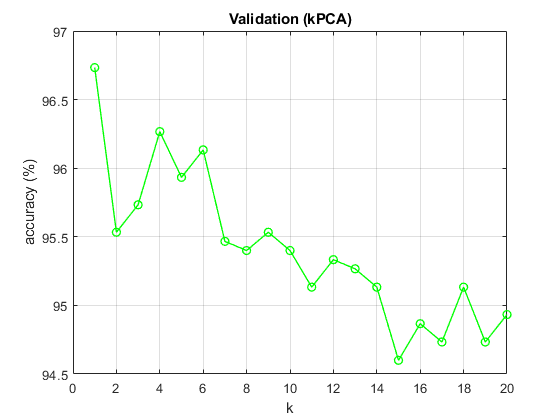

figure;
plot(accuracy,'-o','MarkerIndices',1:1:20,'DisplayName','Accuracy','LineWidth',1,...
    "Color",'g');
title('Validation (kPCA)')
xlabel('k')
ylabel('accuracy (%)')
grid on;

***III. kNN***

% kNN
train = train(:,:)';
test = test(:,:)';
% train_label and test_label stay the same since our 
% train/split remains unchnaged
train_label;
test_label;

% kNN
% Each test row is a query point that needs to be classified and 
% each train row is an observation.
% cross-validation
k = pos(3); %optimal k
idx = knnsearch(double(train),double(test),'K',k,'Distance',"euclidean");
idc = ceil(idx/1050);
pred_labels = mode(idc,2);
acc(3,:) = (1-(length(find(pred_labels~=test_label))/500))*100;
fprintf("Global accuracy score with kPCA data for k = %d is %f percent\n",k,acc(3,:));

Global accuracy score with kPCA data for k = 8 is 94.000000 percent


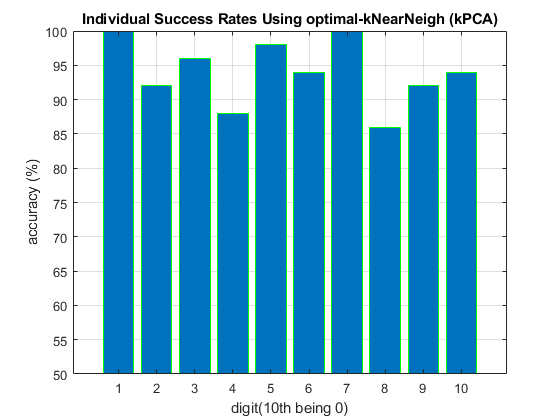


for i = 1:50:500
    success_rate(ceil(i/50),3)=(1-(length(find(pred_labels(i:i+49)~=test_label(i:i+49)))/50))...
                                *100;
end

bar(success_rate(:,3),'EdgeColor','g')
title('Individual Success Rates Using optimal-kNearNeigh (kPCA)')
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')
ylim([50,100])

***IV. kSVM***

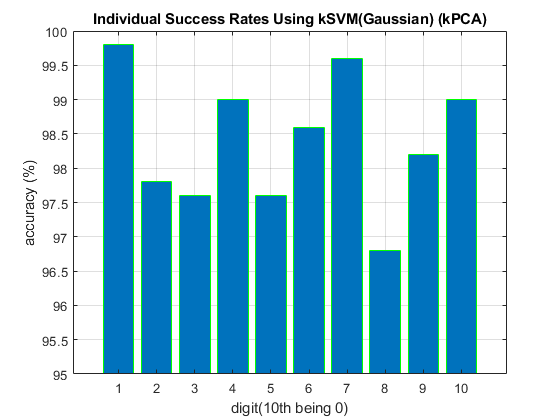

% kSVM
% Performing two-class classification for each digit
for i = 1:10
    k_train_label = zeros(10500,1)-1;
    k_test_label = zeros(500,1)-1;
    k_train_label(find(train_label==i)) = i;
    k_test_label(find(test_label==i)) = i;
    SVMmodel = fitcsvm(double(train),k_train_label,'KernelFunction','rbf'...
                    ,'KernelScale','auto','Standardize',true);
    classes = SVMmodel.ClassNames;
    [label, score] = predict(SVMmodel,double(test));
    correct_label = length(find(label==k_test_label));
    accuracy_score(i,3) = (correct_label/500)*100;
    %fprintf('Global Accuracy Score for digit %d using fitcsvm(rbf) is %f percent\n'...
    %       ,i,accuracy_score(i,:));
end

bar(accuracy_score(:,3),'EdgeColor','g')
title('Individual Success Rates Using kSVM(Gaussian) (kPCA)')
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')
ylim([95,100])

#### -------------------------------------------------

#### Method 4. Laplacian Eigenmaps

***I. Performing LE on the whole dataset using DR-Toolbox for MATLAB***

digits = data(:,:)';
[mapped_data, mapping] = compute_mapping(digits,'Laplacian',dim);

Constructing neighborhood graph...
Computing weight matrices...
Constructing Eigenmaps...


%P = double(digits)*(mapping.M);
%imshow(reshape(P(33,:),[15 15]),[])
train = zeros(dim,1050,10);
test = zeros(dim,50,10);
t = 1;
for i = 1:1100:11000
    train(:,:,t) = mapped_data(i:i+1049,:)';
    test(:,:,t) = mapped_data(i+1050:i+1099,:)';
    t = t+1;
end

***II. Performing Validation for kNN***

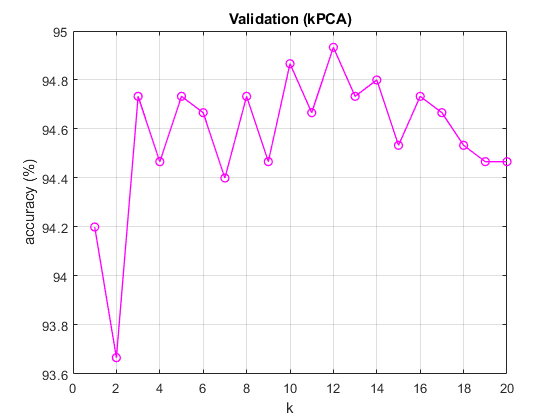

% splitting data into a subset of training-set(x_sub_train) {first 900 examples} 
% and validation-set(x_valid) {next 150 examples} . Last 50 examples are
% left untouched solely for testing.
x_sub_train = zeros(dim,900,10); % [dimx900x10]
x_valid = zeros(dim,150,10); % [dimx150x10]
for i = 1:10
    x_sub_train(:,:,i) = train(:,1:900,i);
    x_valid(:,:,i) = train(:,901:1050,i);
end

% reshaping
x_sub_train = x_sub_train(:,:)';
x_valid = x_valid(:,:)';

% training and validation labels stay the same since train-test split is
% unchanged
subtr_label;
val_label;

accuracy = zeros(20,1);
for k = 1:20
    idx = knnsearch(double(x_sub_train),double(x_valid),'K',k,...
        'Distance',"euclidean");
    idc = ceil(idx/900);
    pred_labels = mode(idc,2);
    accuracy(k,:) = (1-(length(find(pred_labels~=val_label))/1500))*100;
end
[val,pos(4)] = min(abs(accuracy-mean(accuracy)));
figure;
plot(accuracy,'-o','MarkerIndices',1:1:20,'DisplayName','Accuracy','LineWidth',1,...
    "Color",'m');
title('Validation (kPCA)')
xlabel('k')
ylabel('accuracy (%)')
grid on;

***III. kNN***

% kNN
train = train(:,:)';
test = test(:,:)';
% train_label and test_label stay the same since our 
% train/split remains unchnaged
train_label;
test_label;

% kNN
% Each test row is a query point that needs to be classified and 
% each train row is an observation.
% cross-validation
k = pos(4); %optimal k
idx = knnsearch(double(train),double(test),'K',k,'Distance',"euclidean");
idc = ceil(idx/1050);
pred_labels = mode(idc,2);
acc(4,:) = (1-(length(find(pred_labels~=test_label))/500))*100;
fprintf("Global accuracy score with LE data for k = %d is %f percent\n",k,acc(4,:));

Global accuracy score with LE data for k = 15 is 93.400000 percent


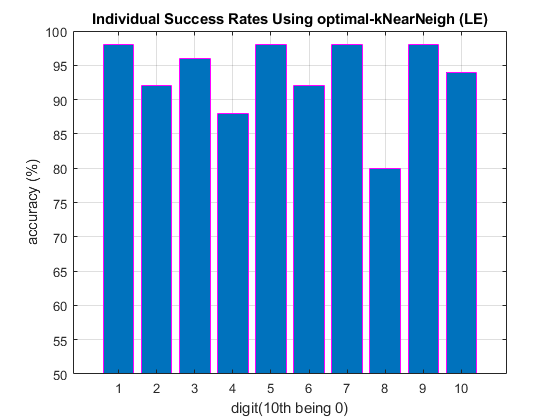


for i = 1:50:500
    success_rate(ceil(i/50),4)=(1-(length(find(pred_labels(i:i+49)~=test_label(i:i+49)))/50))...
                                *100;
end

bar(success_rate(:,4),'EdgeColor','m')
title('Individual Success Rates Using optimal-kNearNeigh (LE)')
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')
ylim([50,100])

***IV. kSVM***

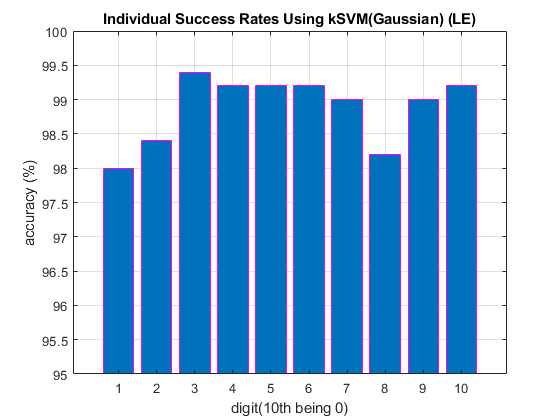

% kSVM
% Performing two-class classification for each digit
for i = 1:10
    k_train_label = zeros(10500,1)-1;
    k_test_label = zeros(500,1)-1;
    k_train_label(find(train_label==i)) = i;
    k_test_label(find(test_label==i)) = i;
    SVMmodel = fitcsvm(double(train),k_train_label,'KernelFunction','rbf'...
                    ,'KernelScale','auto','Standardize',true);
    classes = SVMmodel.ClassNames;
    [label, score] = predict(SVMmodel,double(test));
    correct_label = length(find(label==k_test_label));
    accuracy_score(i,4) = (correct_label/500)*100;
    %fprintf('Global Accuracy Score for digit %d using fitcsvm(rbf) is %f percent\n'...
    %       ,i,accuracy_score(i,:));
end

bar(accuracy_score(:,4),'EdgeColor','m')
title('Individual Success Rates Using kSVM(Gaussian) (LE)')
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')
ylim([95,100])


toc

Elapsed time is 1744.451979 seconds.


#### -------------------------------------------------

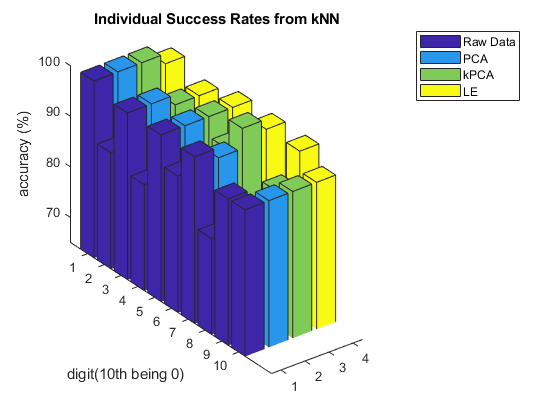

%success_rate
figure
bar3(success_rate)
title('Individual Success Rates from kNN')
grid;
legend({'Raw Data','PCA','kPCA','LE'})
zlim([65,100])
ylabel('digit(10th being 0)')
zlabel('accuracy (%)')

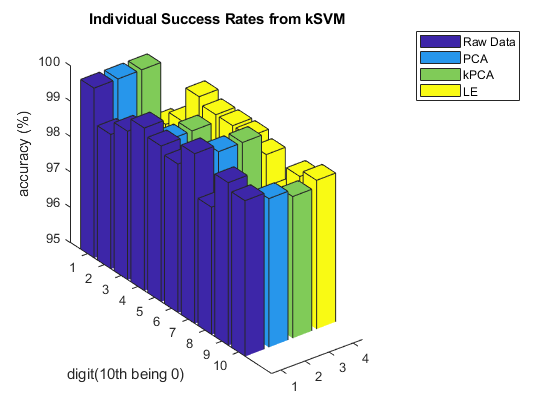


%accuracy_score
figure
bar3(accuracy_score)
title('Individual Success Rates from kSVM')
grid;
legend({'Raw Data','PCA','kPCA','LE'})
zlim([95,100])
ylabel('digit(10th being 0)')
zlabel('accuracy (%)')